# 5 Hz blinking light

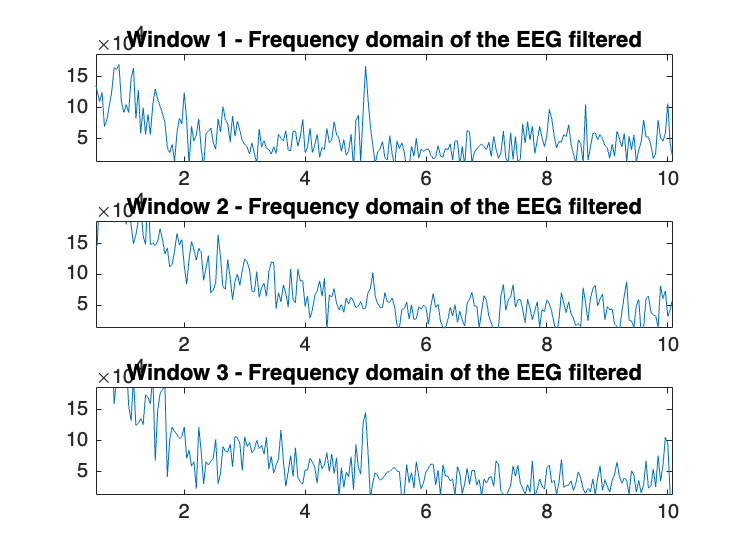

clearvars;
clc;
close all

% The file "5hz-EEG_2022-12-27_16-38-34.h5" contains EEG data of a person
% staring at a light blinking at 5Hz for 25 seconds, then for another 25
% seconds the person had his eyes closed and then again, for 25 seconds,
% the person stared at the same light
fs = 1000;
data = h5read("data/5hz-EEG_2022-12-27_16-38-34.h5", "/20:15:12:22:81:60/raw/channel_4");
data = cast(data, "double");

% figure()
% plot(data)
% title("Raw EEG before filtering")

n_windows = 3;
windowTime = 25; % seconds
windowLen = windowTime*fs;

figure
ax = zeros(1, n_windows);
for ii = 1:n_windows
    window = data(windowLen*(ii-1)+1:windowLen*ii);

    N = length(window);
    f_axis = (0:N-1)/N*fs;
    t_axis = (0:N-1)/fs;
    
    % Filtering the signal
    [b, a] = butter(3, 2*[0.5, 40]/fs);
    window = filtfilt(b, a, window);
    window = bandstop(window, [45, 55], fs);
    
%     figure()
%     plot(window)
%     title(sprintf("Window %u - EEG after filtering", ii))
    
    ax(ii) = subplot(3,1,ii);
    plot(f_axis, abs(fft(window-mean(window))))
    title(sprintf("Window %u - Frequency domain of the EEG filtered", ii))
end
linkaxes(ax);

subplot(3,1,1)
xlim([0.54 10.07])
ylim([12883 185070])
zlim([-1.00 1.00])

## 7.4 Hz blinking light

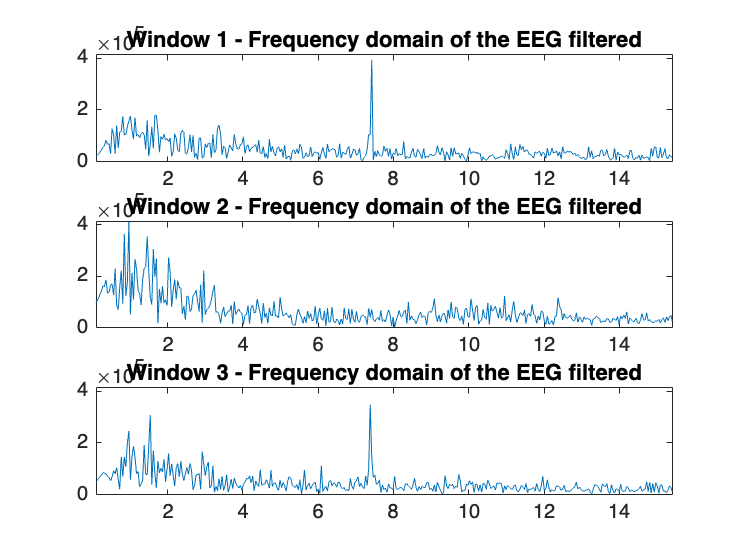

clearvars;
clc;
close all

% The file "7.4hz-EEG_2022-12-27_16-38-34.h5" contains EEG data of a person
% staring at a light blinking at 7.4Hz for 25 seconds, then for another 25
% seconds the person had his eyes closed and then again, for 25 seconds,
% the person stared at the same light
fs = 1000;
data = h5read("data/7.4hz-EEG_2022-12-27_16-32-02.h5", "/20:15:12:22:81:60/raw/channel_4");
data = cast(data, "double");

% figure()
% plot(data)
% title("Raw EEG before filtering")

n_windows = 3;
windowTime = 24.650; % seconds
windowLen = windowTime*fs;

figure
ax = zeros(1, n_windows);
for ii = 1:n_windows
    window = data(windowLen*(ii-1)+1:windowLen*ii);

    N = length(window);
    f_axis = (0:N-1)/N*fs;
    t_axis = (0:N-1)/fs;
    
    % Filtering the signal
    [b, a] = butter(3, 2*[0.5, 40]/fs);
    window = filtfilt(b, a, window);
    window = bandstop(window, [45, 55], fs);
    
%     figure()
%     plot(window)
%     title(sprintf("Window %u - EEG after filtering", ii))
    
    ax(ii) = subplot(3,1,ii);
    plot(f_axis, abs(fft(window-mean(window))))
    title(sprintf("Window %u - Frequency domain of the EEG filtered", ii))
end
linkaxes(ax);

subplot(3,1,1)
xlim([0.1 15.4])
ylim([-1774 411624])
zlim([-1.00 1.00])

## 11 Hz blinking light

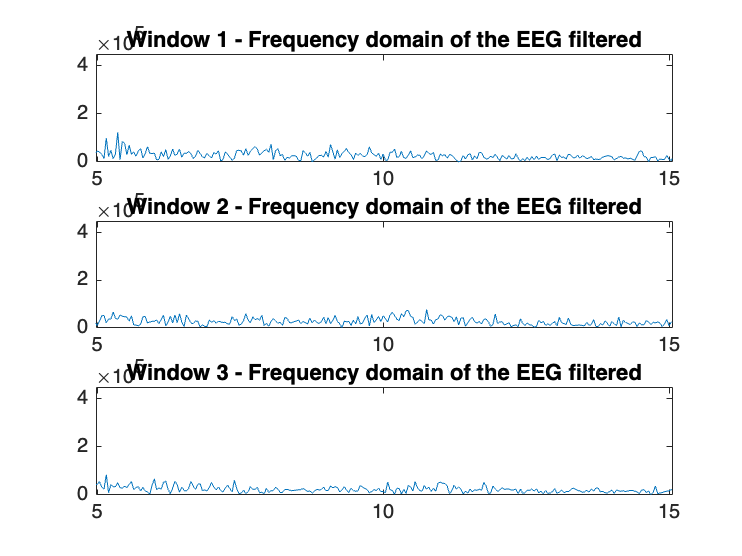

clearvars;
clc;
close all

% The file "11hz-EEG_2022-12-27_16-38-34.h5" contains EEG data of a person
% staring at a light blinking at 11Hz for 25 seconds, then for another 25
% seconds the person had his eyes closed and then again, for 25 seconds,
% the person stared at the same light
fs = 1000;
data = h5read("data/11hz-EEG_2022-12-27_16-35-54.h5", "/20:15:12:22:81:60/raw/channel_4");
data = cast(data, "double");

% figure()
% plot(data)
% title("Raw EEG before filtering")

n_windows = 3;
windowTime = 25; % seconds
windowLen = windowTime*fs;

figure
ax = zeros(1, n_windows);
for ii = 1:n_windows
    window = data(windowLen*(ii-1)+1:windowLen*ii);

    N = length(window);
    f_axis = (0:N-1)/N*fs;
    t_axis = (0:N-1)/fs;
    
    % Filtering the signal
    [b, a] = butter(3, 2*[0.5, 40]/fs);
    window = filtfilt(b, a, window);
    window = bandstop(window, [45, 55], fs);
    
%     figure()
%     plot(window)
%     title(sprintf("Window %u - EEG after filtering", ii))
    
    ax(ii) = subplot(3,1,ii);
    plot(f_axis, abs(fft(window-mean(window))))
    title(sprintf("Window %u - Frequency domain of the EEG filtered", ii))
end
linkaxes(ax);

subplot(3,1,1)
xlim([4.98 15.05])
ylim([0 444190])
zlim([-1.00 1.00])

## 17 Hz blinking light

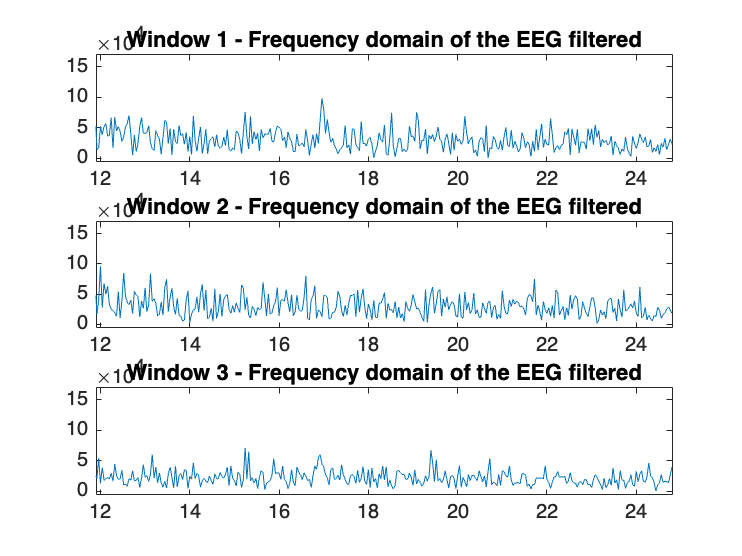

clearvars;
clc;
close all

% The file "17hz-EEG_2022-12-27_16-38-34.h5" contains EEG data of a person
% staring at a light blinking at 17Hz for 25 seconds, then for another 25
% seconds the person had his eyes closed and then again, for 25 seconds,
% the person stared at the same light
fs = 1000;
data = h5read("data/17hz-EEG_2022-12-27_16-41-29.h5", "/20:15:12:22:81:60/raw/channel_4");
data = cast(data, "double");

% figure()
% plot(data)
% title("Raw EEG before filtering")

n_windows = 3;
windowTime = 25; % seconds
windowLen = windowTime*fs;

figure
ax = zeros(1, n_windows);
for ii = 1:n_windows
    window = data(windowLen*(ii-1)+1:windowLen*ii);

    N = length(window);
    f_axis = (0:N-1)/N*fs;
    t_axis = (0:N-1)/fs;
    
    % Filtering the signal
    [b, a] = butter(3, 2*[0.5, 40]/fs);
    window = filtfilt(b, a, window);
    window = bandstop(window, [45, 55], fs);
    
%     figure()
%     plot(window)
%     title(sprintf("Window %u - EEG after filtering", ii))
    
    ax(ii) = subplot(3,1,ii);
    plot(f_axis, abs(fft(window-mean(window))))
    title(sprintf("Window %u - Frequency domain of the EEG filtered", ii))
end
linkaxes(ax);

subplot(3,1,1)
xlim([11.9 24.8])
ylim([-6202 169609])
zlim([-1.00 1.00])